# Load Laser Scan Data from File

Load a down-sampleed data set consisting of laser scans collected from a mobile robot in an indoor environment. The average displacement between every two scans is around 0.6 meters

load('offlineSlamData.mat');
dir offlineSlamData.mat

offlineSlamData.mat  



# Run SLAM Algorithm, Construct Optimized Map and Plot Trajectory of the Robot

maxLidarRange = 8;
mapResolution = 20;
slamAlg = lidarSLAM(mapResolution, maxLidarRange);
slamAlg.LoopClosureThreshold = 210;  
slamAlg.LoopClosureSearchRadius = 8;

# Observe the Map building Process with initial 10 scans

for i=1:10
    [isScanAccepted, loopClosureInfo, optimizationInfo] = addScan(slamAlg, scans{i});
    if isScanAccepted
        fprintf('Added scan %d \n', i);
    end
end

Added scan 1 
Added scan 2 
Added scan 3 
Added scan 4 
Added scan 5 
Added scan 6 
Added scan 7 
Added scan 8 
Added scan 9 
Added scan 10 


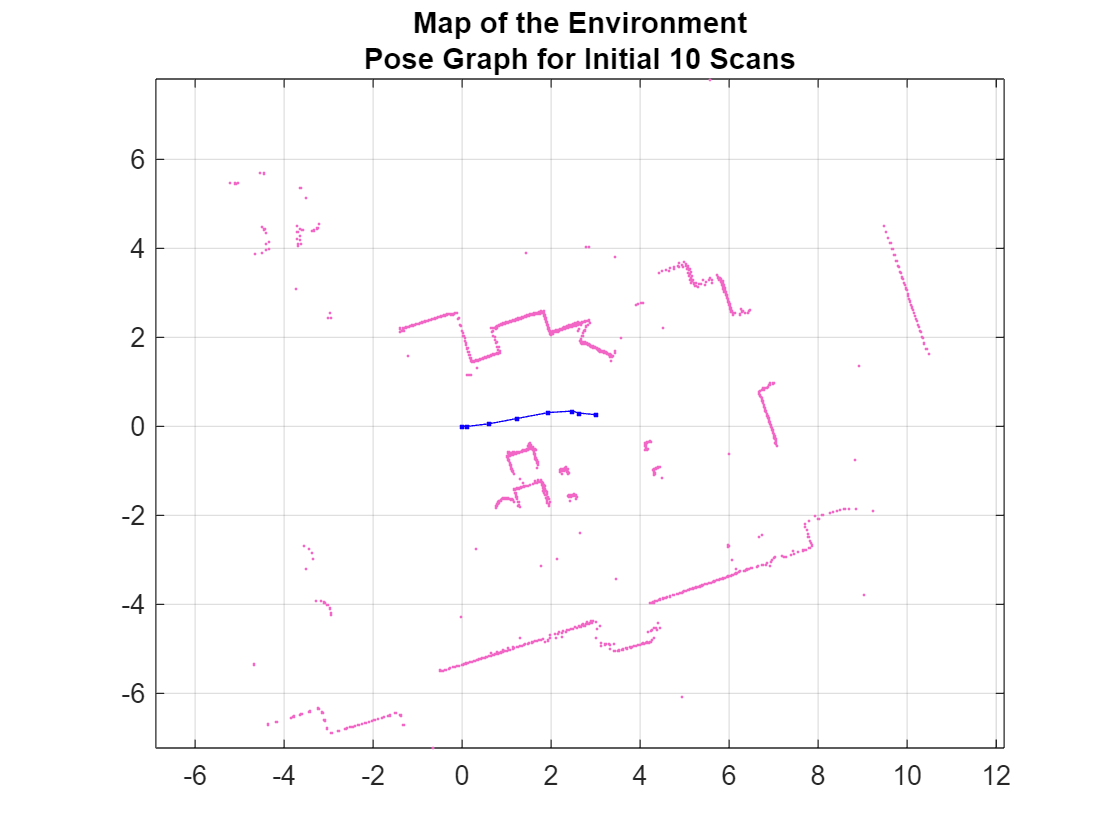

figure;
show(slamAlg);
title({'Map of the Environment','Pose Graph for Initial 10 Scans'});

# Observe the effect of loop closures and the optimization process

for i=10:length(scans)
    [isScanAccepted, loopClosureInfo, optimizationInfo] = addScan(slamAlg, scans{i});
    if ~isScanAccepted
        continue;
    end
end 

# Visualize the Contructed Map and Trajectory of the Robot

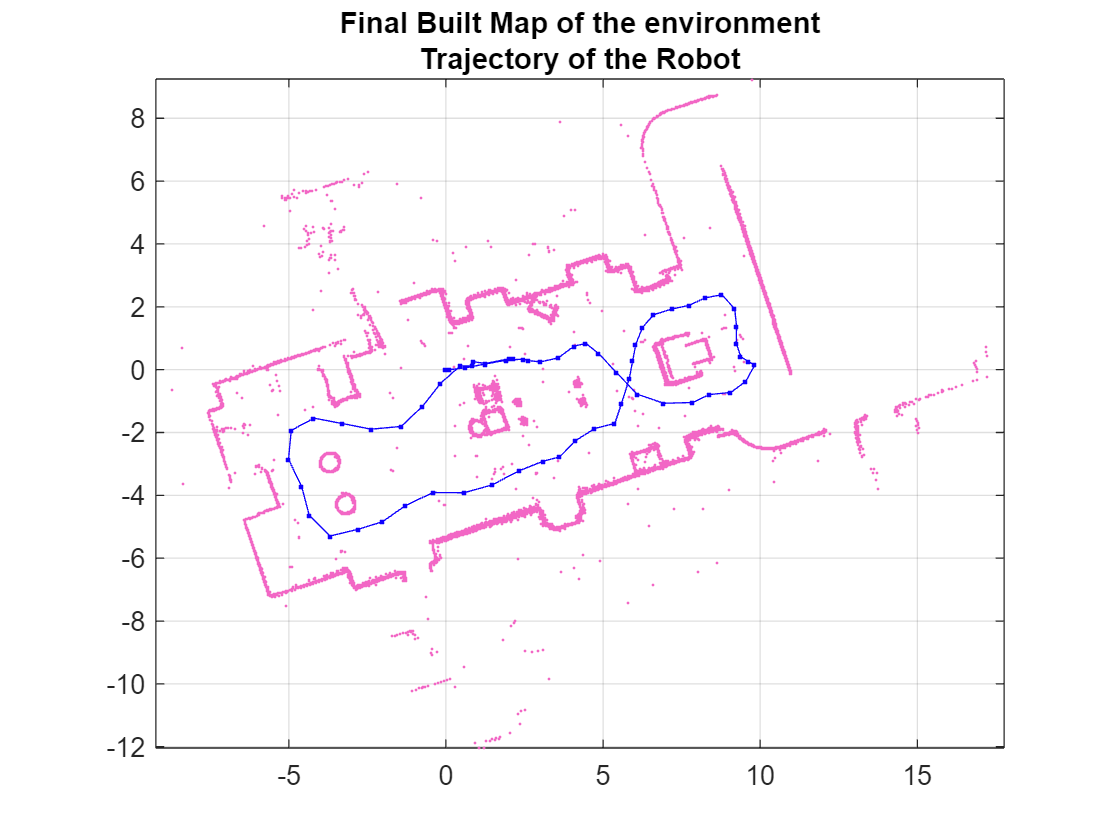

figure
show(slamAlg);
title({'Final Built Map of the environment', 'Trajectory of the Robot'});

# Build Occupancy Grid Map

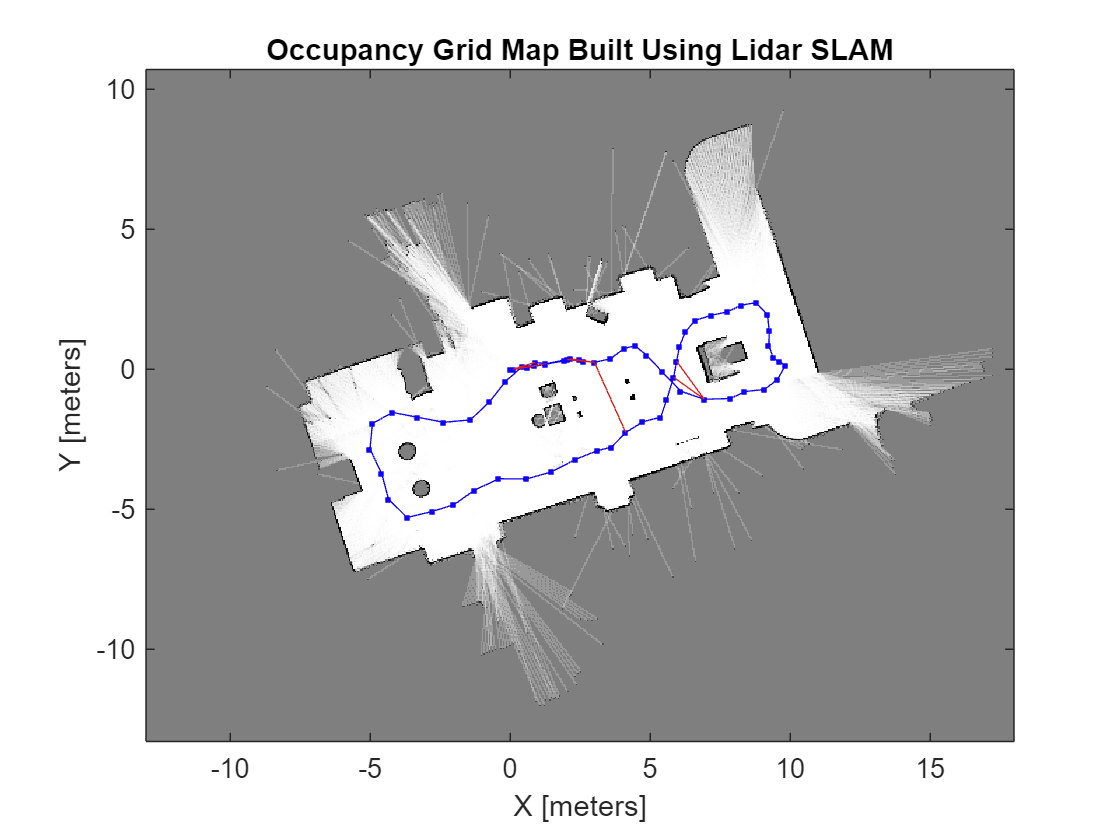

[scans, optimizedPoses]  = scansAndPoses(slamAlg);
map = buildMap(scans, optimizedPoses, mapResolution, maxLidarRange);
figure; 
show(map);
hold on
show(slamAlg.PoseGraph, 'IDs', 'off');
hold off
title('Occupancy Grid Map Built Using Lidar SLAM');